%%Dynamics of Planar Mechanisms, lab work 1
%Done by;
%Gateru Felix Wanyoike    -- ENM221-
%Washington Kigani Kamadi -- ENM221-0063/2017
%Michael Kimani Gitau     -- ENM221-
%Brown                    -- ENM221-

%Section a
%An implementation of The Chebyshev spacing formula is created as a
%   function called chebyshev
%It takes 3 arguments, the maximum and minimum value of the range and the
%   number of precision points.

%%Using chebyshev to find the precision points
%The precision points are stored in a column vector called precisionPoints
precisionPoints = chebyshev(15, 165, 3);

input = precisionPoints

input =   154.9519
   90.0000
   25.0481


%The required function
% theta4 = 65 + 0.43*theta2
%The above is implemented as a function taking one argument for theta2 and
%   giving as output theta4

output = rel(input)

output =   131.6293
  103.7000
   75.7707


%Solving for the values of K1, K2 and K3 using the freudenstein's equation
K = (freudenstein(input, output));

%Solving for the lengths of the links
%a,b and c -- given that the length of d is fixed
fixed = 0.410

fixed = 0.4100

crank = (fixed/(K(1,1)))

crank = -0.0577

follower = (fixed/(K(2,1)))

follower = -0.1203

coupler = sqrt((crank^2)+(follower^2)+(fixed^2) - (2*crank*follower*(K(3,1))))

coupler = 0.4424


%%Solving for the transmission angles
%Using the range of input angles from 30 degrees to 150degrees
input = (0 : 5: 280)'

input =      0
     5
    10
    15
    20
    25
    30
    35
    40
    45


%%Computing the transmission angle
transmission = transmissionAngle(crank,coupler,follower,fixed,input)

transmission =    85.3874
   85.4847
   85.7758
   86.2583
   86.9282
   87.7802
   88.8075
   90.0025
   91.3564
   92.8599


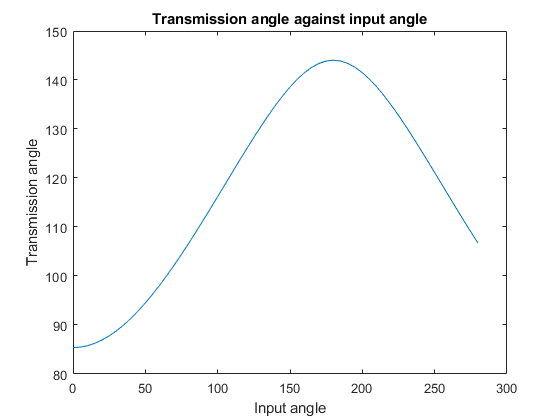

%%Plotting the values of the transmission angle against the input angle
plot(input, transmission)
title ('Transmission angle against input angle')
xlabel('Input angle')
ylabel('Transmission angle')